[y, fs] = audioread('s5.wav');
% mu-量化
y_new = mulaw(y, 225);
% 均匀量化
yh_8 = fxquant(mulaw(y, 225), 8, 'round', 'sat');
yh_9 = fxquant(mulaw(y, 225), 9, 'round', 'sat');
yh_10 = fxquant(mulaw(y, 225), 10, 'round', 'sat');
yh_11 = fxquant(mulaw(y, 225), 11, 'round', 'sat');
yh_12 = fxquant(mulaw(y, 225), 12, 'round', 'sat');
% s = y - yh_8
[snr_8, e_8] = SNR(yh_8, y_new);

sum_sig = 4.8474e+03

sum_err = 0.0986

snr = 46.9183

[snr_9, e_9] = SNR(yh_9, y_new);

sum_sig = 4.8474e+03

sum_err = 0.0256

snr = 52.7657

[snr_10, e_10] = SNR(yh_10, y_new);

sum_sig = 4.8474e+03

sum_err = 0.0060

snr = 59.0761

[snr_11, e_11] = SNR(yh_11, y_new);

sum_sig = 4.8474e+03

sum_err = 0.0018

snr = 64.2862

[snr_12, e_12] = SNR(yh_12, y_new);

sum_sig = 4.8474e+03

sum_err = 4.0370e-04

snr = 70.7945

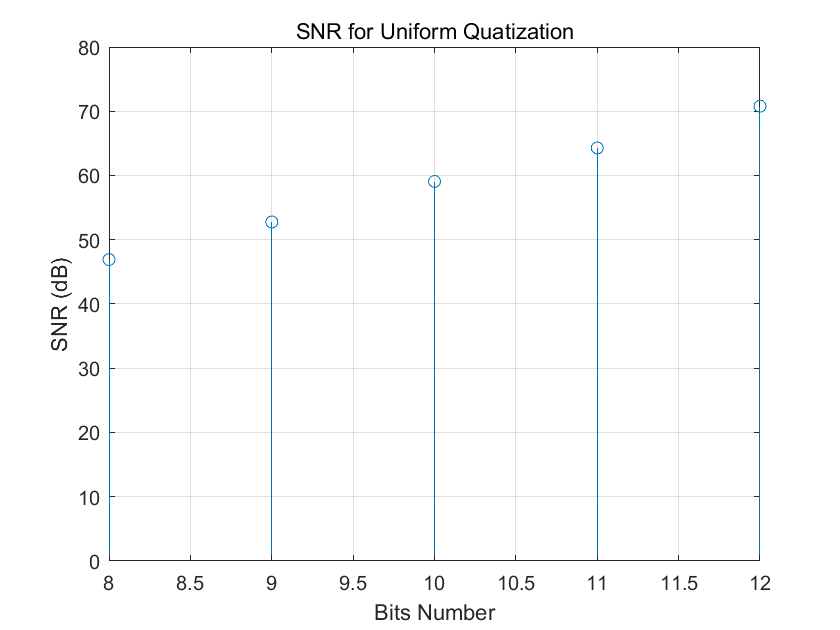

bit = [8,9,10,11,12];
snr = [snr_8, snr_9, snr_10, snr_11, snr_12];
figure
stem(bit, snr), xlabel('Bits Number'), ylabel('SNR (dB)'), title('SNR for Uniform Quatization')
grid on
saveas(gcf, "D:/作业提交/大三 下/语音信号处理/lab10/P2_b.png", 'png')

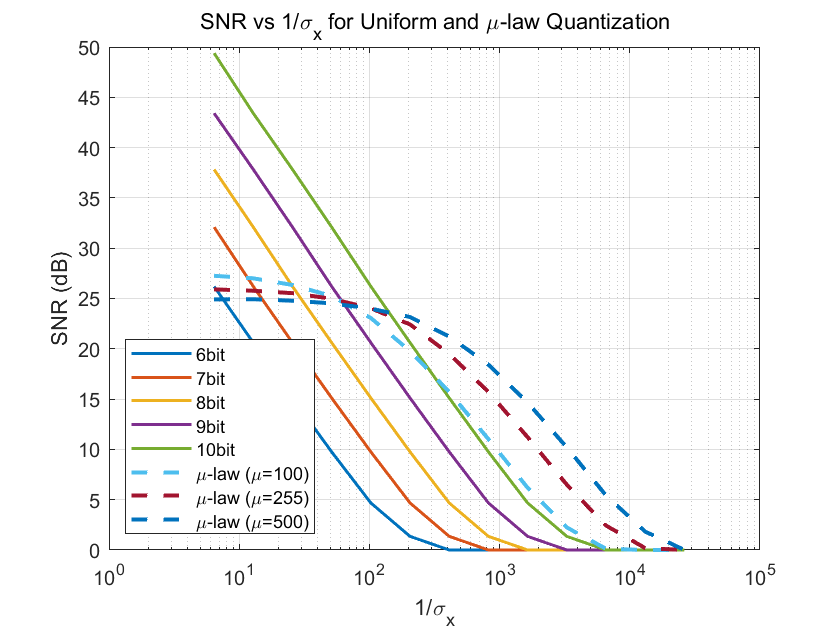

% [y, fs] = audioread('s5.wav');
% % mu-量化
% y_new = mulaw(y, 225);
% % 均匀量化
% yh_8 = fxquant(mulaw(y, 225), 8, 'round', 'sat');
% yh_9 = fxquant(mulaw(y, 225), 9, 'round', 'sat');
% yh_10 = fxquant(mulaw(y, 225), 10, 'round', 'sat');
% yh_ = fxquant(mulaw(y, 225), 11, 'round', 'sat');

[x, Fs] = audioread('s5.wav');
x = x(:, 1); 

% 参数设置
factors = 2.^(0:-1:-12); 
mu_values = [100, 255, 500];
bits_uniform = 6:10;

% 初始化存储矩阵
snr_uniform = zeros(length(factors), length(bits_uniform));
snr_mulaw = zeros(length(factors), length(mu_values));
inv_sigma_x = zeros(length(factors), 1);

% 计算不同幅度下的SNR
for i = 1:length(factors)
    x_scaled = x * factors(i);
    sigma_x = std(x_scaled);
    inv_sigma_x(i) = 1 / sigma_x;
    
    % 均匀量化
    for j = 1:length(bits_uniform)
        x_quant = fxquant(x_scaled, bits_uniform(j), 'round', 'sat');
        snr_uniform(i,j) = 10 * log10( sum(x_scaled.^2) / sum((x_scaled - x_quant).^2) );
    end
    
    % μ-law量化 (6 bits)
    for k = 1:length(mu_values)
        % μ-law压缩
        y = mulaw(x_scaled, mu_values(k));
        % 均匀量化（6 bits）
        y_quant = fxquant(y, 6, 'round', 'sat');
        % μ-law扩展
        x_recon = mulawinv(y_quant, mu_values(k));
        % 计算 SNR (dB)
        snr_mulaw(i,k) = 10 * log10( sum(x_scaled.^2) / sum((x_scaled - x_recon).^2) );
    end
end

figure;
semilogx(inv_sigma_x, snr_uniform, 'LineWidth', 1.5); hold on;
semilogx(inv_sigma_x, snr_mulaw, '--', 'LineWidth', 2);
xlabel('1/\sigma_x'); ylabel('SNR (dB)');
title('SNR vs 1/\sigma_x for Uniform and \mu-law Quantization');
grid on;

legend_labels = [...
    arrayfun(@(b) sprintf('%dbit', b), bits_uniform, 'UniformOutput', false), ...
    arrayfun(@(mu) sprintf('\\mu-law (\\mu=%d)', mu), mu_values, 'UniformOutput', false) ...
];
legend(legend_labels, 'Location', 'southwest');
saveas(gcf, "D:/作业提交/大三 下/语音信号处理/lab10/P2_a.png", 'png')

这里mu-law量化时，在均匀量化阶段选择用6bit。

function y = mulaw(x, mu)
    y = sign(x) .* log(1 + mu * abs(x)) / log(1 + mu);
end

function [snr, e] = SNR(xh, x)
    L = length(x);
    sum_sig = 0;
    sum_err = 0;
    for i=1:L
        sum_sig = sum_sig + x(i).^2;   % 分号！！！
        sum_err = sum_err + (x(i)-xh(i)).^2;   % 分号！！！
    end
    sum_sig
    sum_err
    snr = 10*log10(sum_sig/sum_err)
    e = mulaw(xh, 225) - x;
%     mean(e)
end